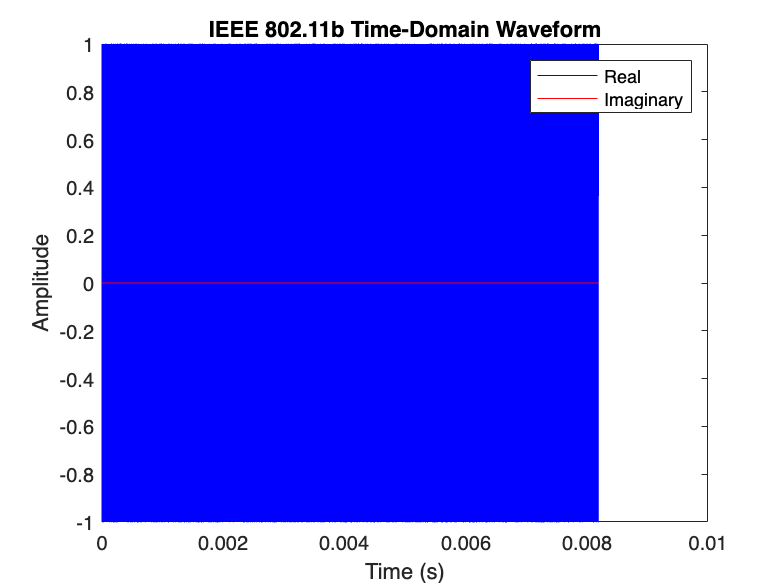

load('test1.mat');

% Extract relevant information
waveform = waveStruct.waveform;
Fs = waveStruct.Fs;

% Plot the time-domain waveform
time = (0:length(waveform)-1) / Fs;
figure;
plot(time, real(waveform), 'b', time, imag(waveform), 'r');
title('IEEE 802.11b Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Real', 'Imaginary');

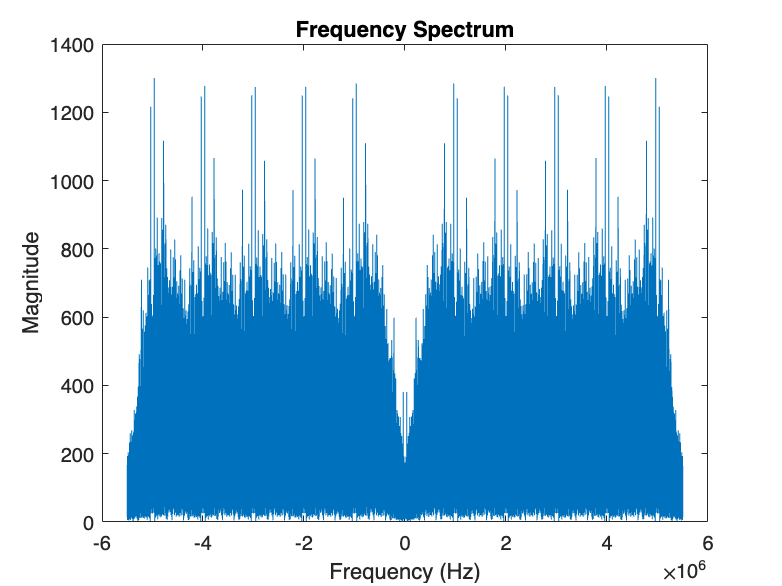


% Compute and plot the frequency-domain spectrum
spectrum = fftshift(fft(waveform));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

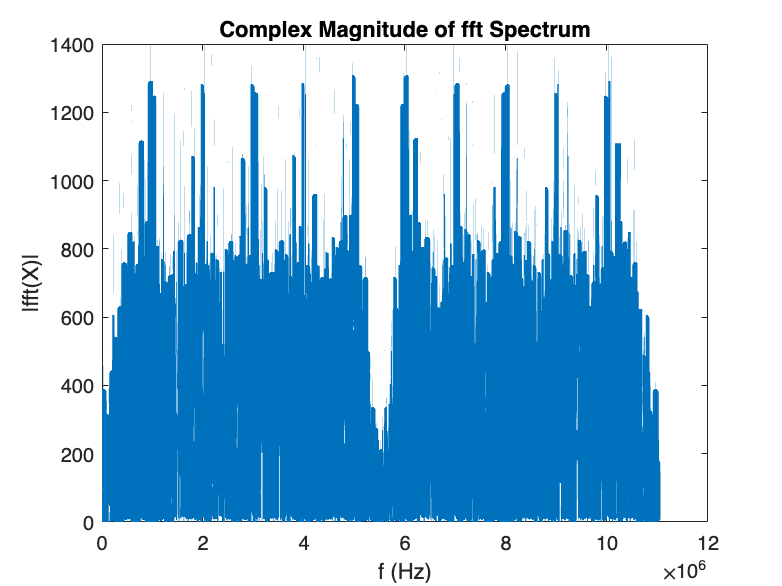


t = time;
L = length(waveform);
Y = fft(waveform);
plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

## try to run through low pass


top_end = 3044000

top_end = 3044000

low_waveform = lowpass(waveform,top_end,Fs);
%low_end = 2978000
%low_waveform = highpass(low_waveform,low_end,Fs);


## frequency shift down 1.22 MHz


% Assuming 'signal' is your digital signal and 'sample_rate' is the sampling rate
t = time;
negative_frequency_offset = -1.22e6;  % Negative frequency offset in Hertz
shifter = exp(1i * 2 * pi * negative_frequency_offset * t);
shifter = shifter.';
shifted_signal = low_waveform .* shifter;
top_end = 1000000

top_end = 1000000

shifted_signal = lowpass(shifted_signal,top_end,Fs);
shifter = [];


## graph results

disp("hi");

hi


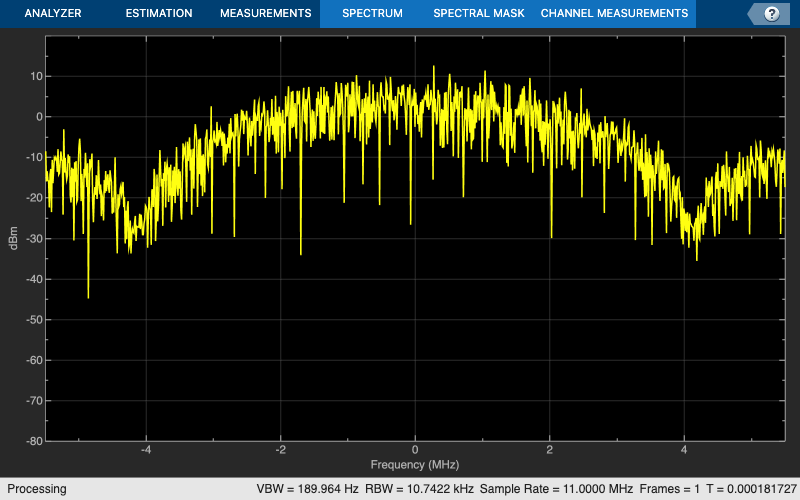


specAnal = spectrumAnalyzer(SampleRate=11e6);
specAnal(modulated_signal.')

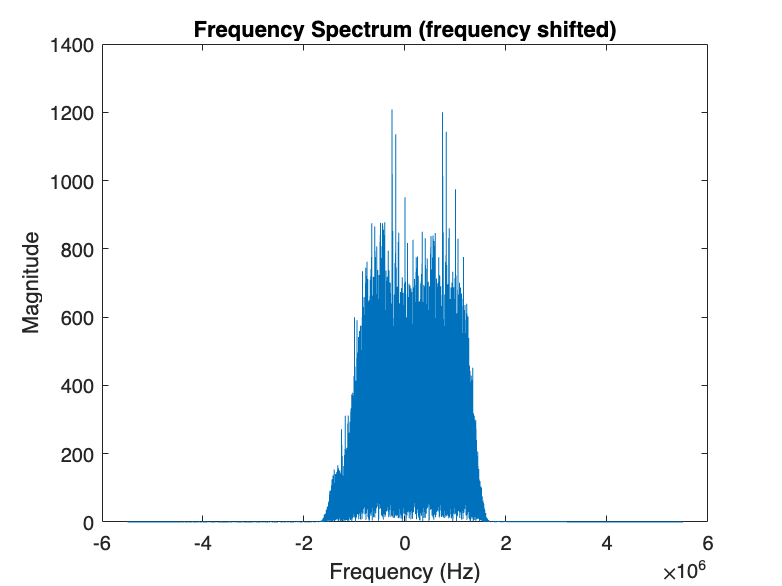


spectrum = fftshift(fft(shifted_signal));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum (frequency shifted)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

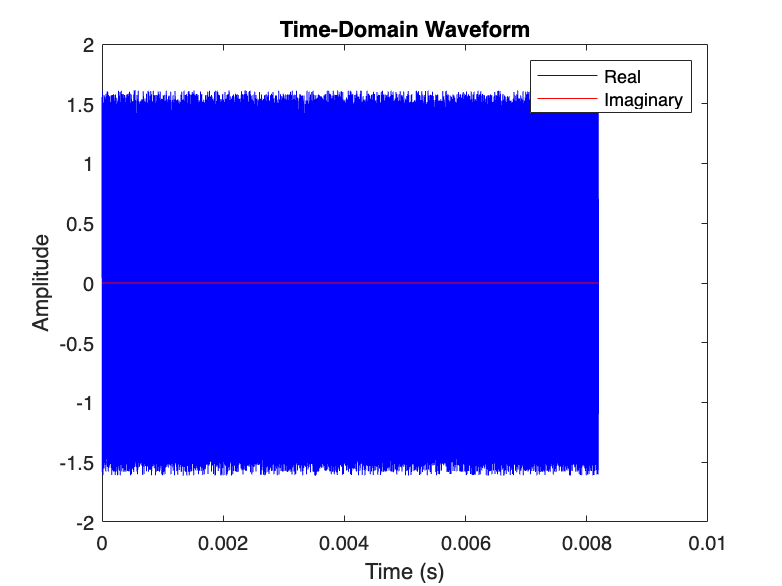



% Plot the time-domain waveform
time = (0:length(low_waveform)-1) / Fs;
figure;
plot(time, real(low_waveform), 'b', time, imag(low_waveform), 'r');
title('Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Real', 'Imaginary');


%
%
%
%
%
%
%

smallw = waveform(1:length(waveform)/11/32,:);
t = (0:length(smallw)-1) / Fs;
instantaneous_phase = unwrap(angle(hilbert(smallw)));


% Compute the frequency deviation
frequency_deviation = diff(instantaneous_phase) / (2 * pi * (t(2) - t(1)));

% Plot the waveform
subplot(4, 1, 1);
plot(t, smallw);

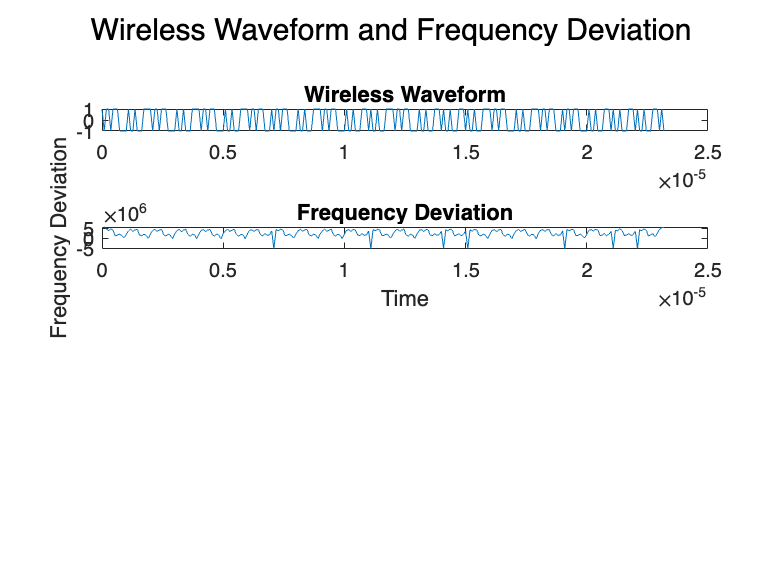

title('Wireless Waveform');

% Plot the frequency deviation
subplot(4, 1, 2);
plot(t(2:end), frequency_deviation);
title('Frequency Deviation');
xlabel('Time');
ylabel('Frequency Deviation');

% Display the plot
sgtitle('Wireless Waveform and Frequency Deviation');


backup_waveform = waveform;
waveform = shifted_signal;

smallw = waveform(1:length(waveform)/11/32,:);
waveform = backup_waveform;
t = (0:length(smallw)-1) / Fs;
instantaneous_phase = unwrap(angle(hilbert(smallw)));


% Compute the frequency deviation
frequency_deviation = diff(instantaneous_phase) / (2 * pi * (t(2) - t(1)));

% Plot the waveform
figure;
plot(t, smallw);

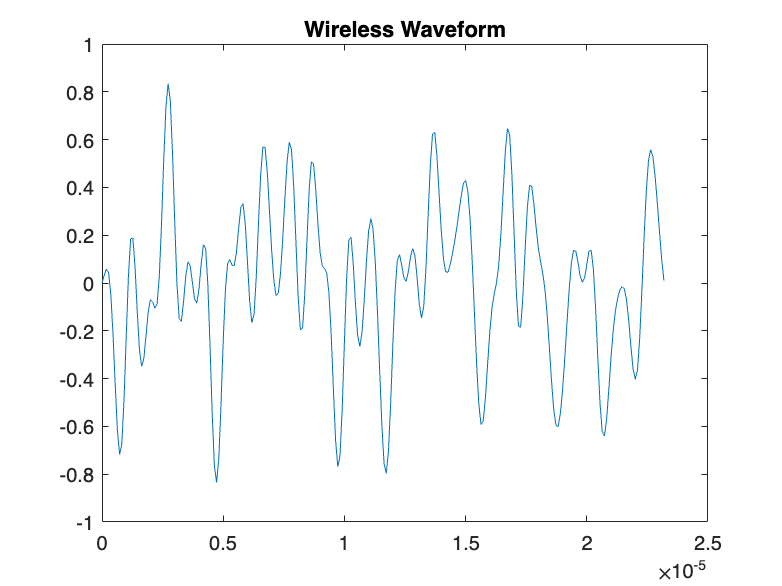

title('Wireless Waveform');

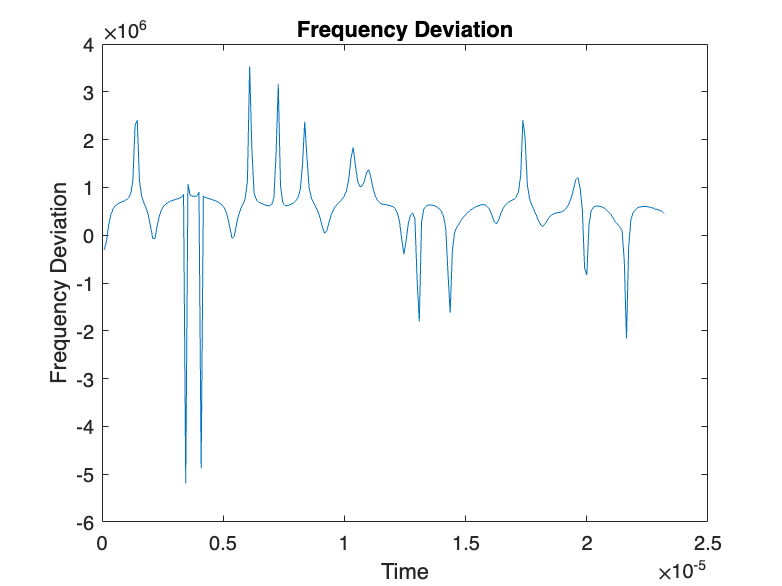


%subplot(4, 1, 4);
figure;
plot(t(2:end), frequency_deviation);
title('Frequency Deviation');
xlabel('Time');
ylabel('Frequency Deviation');

%sgtitle('Wireless Waveform and Frequency Deviation (filtered)');
